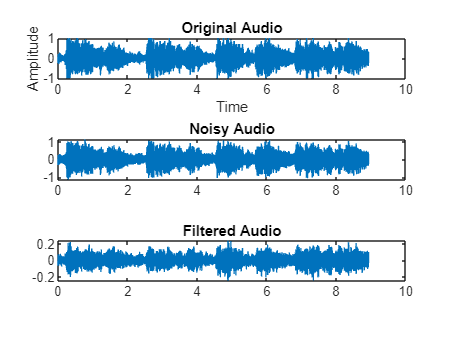

clc; clear; close all;

%% Step 1: Load Built-in Audio
load handel               % Loads 'y' and 'Fs'
x = y / max(abs(y));      % Normalize
sound(x, Fs);             % Play original audio

%% Step 2: Add White Gaussian Noise
noise = 0.05 * randn(size(x));
noisy_x = x + noise;
sound(noisy_x, Fs);       % Play noisy signal

%% Step 3: Apply Manual FIR Low-Pass Filter (Moving Average)
N = 20;                        % Filter order
h = ones(1, N) / N;            % Filter coefficients
filtered_x = conv(noisy_x, h, 'same');  % Apply filter
sound(filtered_x, Fs);        % Play filtered signal

%% Step 4: Plot Time Domain Signals
t = (0:length(x)-1) / Fs;

figure('Name', 'Time Domain Signals');
subplot(3,1,1); plot(t, x); title('Original Audio'); xlabel('Time'); ylabel('Amplitude');
subplot(3,1,2); plot(t, noisy_x); title('Noisy Audio');
subplot(3,1,3); plot(t, filtered_x); title('Filtered Audio');

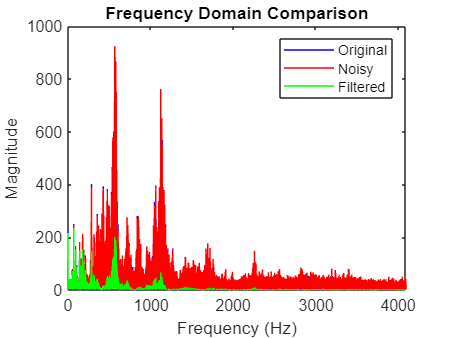


%% Step 5: Frequency Domain Analysis (FFT)
Nfft = length(x);
f = (0:Nfft-1)*(Fs/Nfft);

X = abs(fft(x));
NX = abs(fft(noisy_x));
FX = abs(fft(filtered_x));

figure('Name', 'Frequency Spectrum');
plot(f, X, 'b'); hold on;
plot(f, NX, 'r'); 
plot(f, FX, 'g');
legend('Original', 'Noisy', 'Filtered');
xlim([0 Fs/2]);
title('Frequency Domain Comparison');
xlabel('Frequency (Hz)'); ylabel('Magnitude');


%% Step 6: Optional: Save Outputs
audiowrite('noisy_handel.wav', noisy_x, Fs);

audiowrite('filtered_handel.wav', filtered_x, Fs);
saveas(gcf, 'output/frequency_spectrum.png');

Error using saveas
Invalid or missing path: output/frequency_spectrum.png